# 一些数据分析方法

## 线性相关性-协方差矩阵

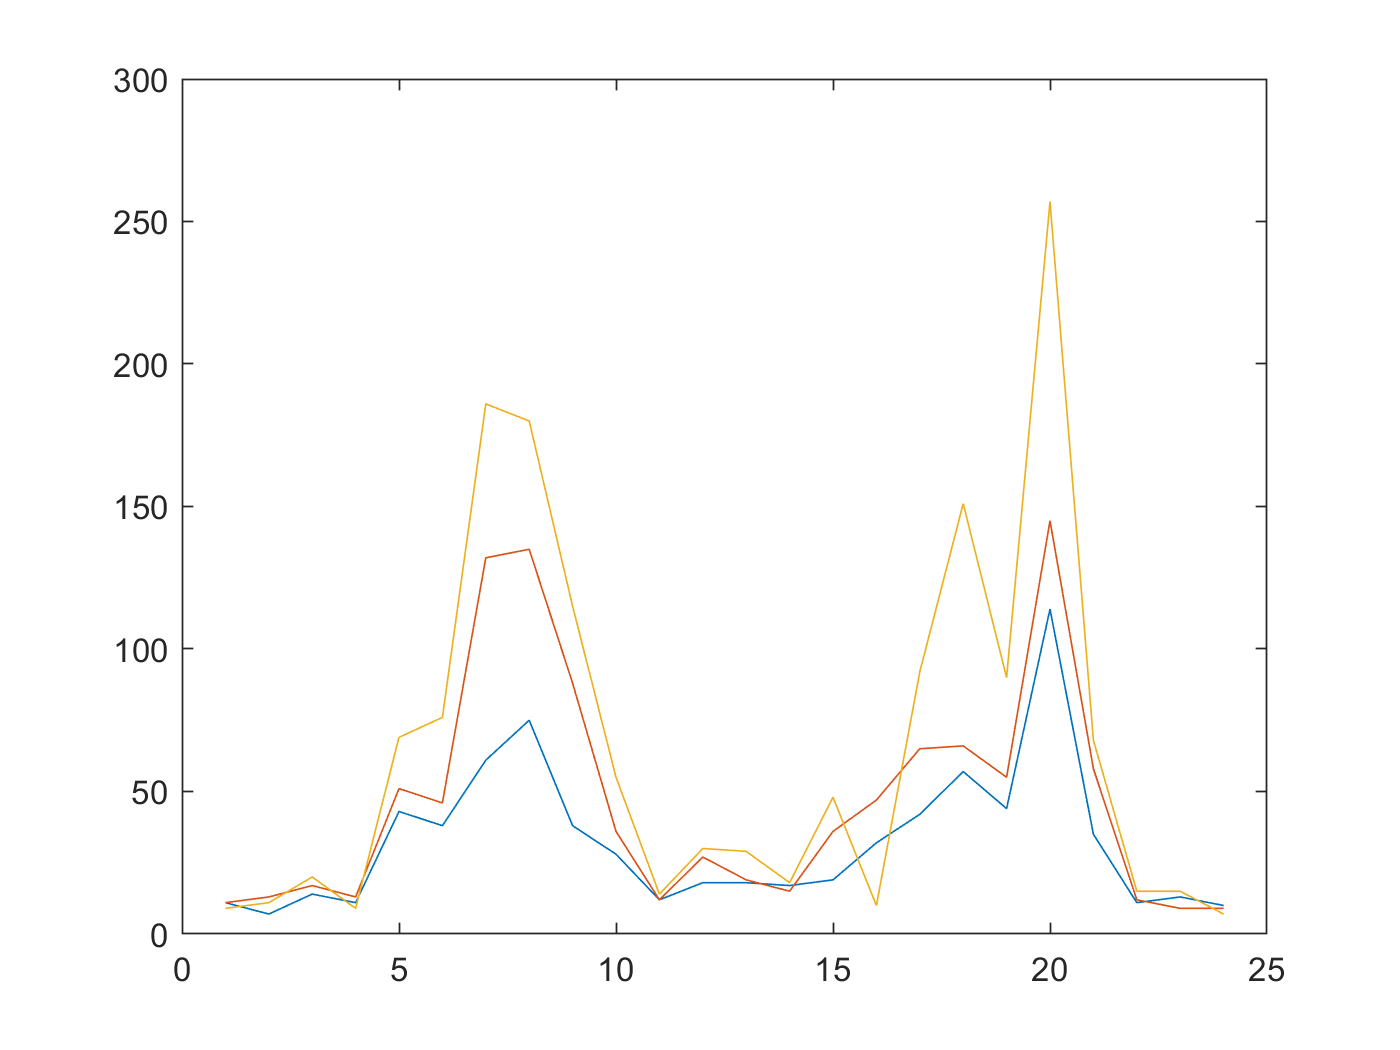

% https://ww2.mathworks.cn/help/matlab/data_analysis/linear-correlation.html?action=changeCountry&s_tid=gn_loc_drop
load count.dat
plot(count)

corrcoef(count)

ans =     1.0000    0.9331    0.9599
    0.9331    1.0000    0.9553
    0.9599    0.9553    1.0000


% 检验协方差
% empty_box(E),water_box(W)
% 1.同一个材料不同位置之间的关联
% corrcoef(E),corrcoef(W)
% 2.差值之间的关联
% corrcoef(E-W)


## PAC 主成分分析

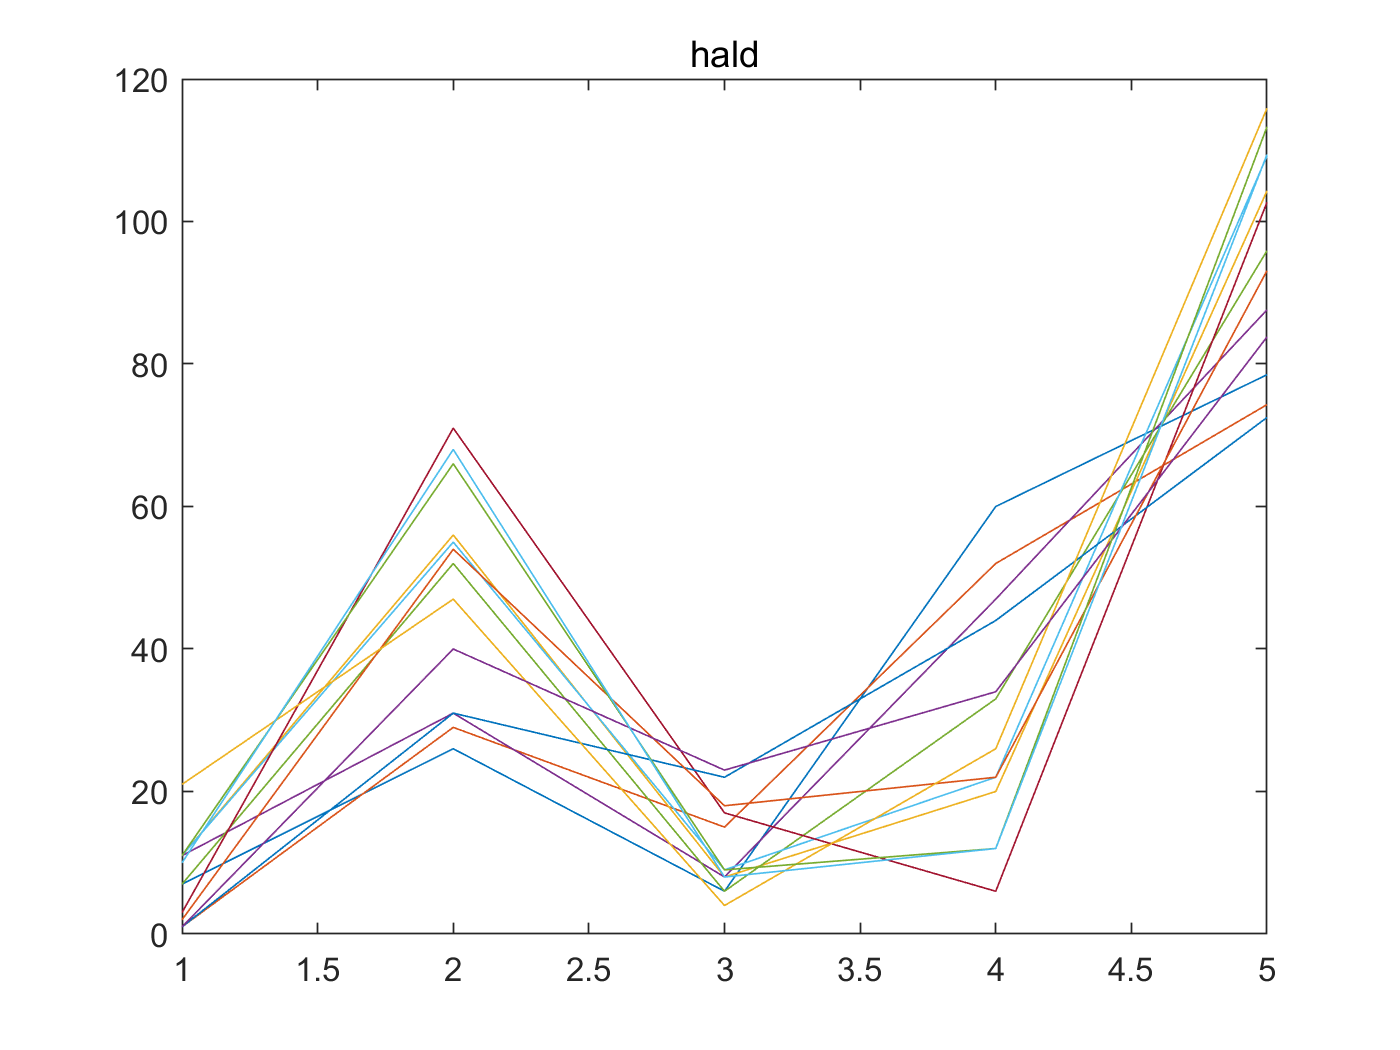

% https://ww2.mathworks.cn/help/stats/pca.html?searchHighlight=主成分&s_tid=srchtitle
load hald
plot(hald');title('hald')

coeff = pca(ingredients)

coeff =    -0.0678   -0.6460    0.5673    0.5062
   -0.6785   -0.0200   -0.5440    0.4933
    0.0290    0.7553    0.4036    0.5156
    0.7309   -0.1085   -0.4684    0.4844


% PAC太复杂了,现在考虑简单一点的情况,svd分解
% https://zh.wikipedia.org/wiki/奇异值分解
% 与零奇异值对应的右奇异向量生成矩阵M的零空间，与非零奇异值对应的左奇异向量则生成矩阵M的列空间
% 与非零奇异值对应的右奇异向量则生成矩阵M的行空间
[U,S,V] = svd(hald) %U*S*V' = hald

U =    -0.4082   -0.7071    0.5774
   -0.4082    0.7071    0.5774
   -0.8165   -0.0000   -0.5774


S =    15.0000         0         0         0         0         0
         0    5.9161         0         0         0         0
         0         0    0.0000         0         0         0


V =    -0.4082    0.5976    0.4889   -0.0761   -0.2393   -0.4172
   -0.4082    0.3586    0.0523    0.1896    0.4404    0.6871
   -0.4082    0.1195   -0.6444   -0.5732   -0.2646    0.0719
   -0.4082   -0.1195   -0.3721    0.7627   -0.2288   -0.2157
   -0.4082   -0.3586    0.0237   -0.1835    0.6864   -0.4466
   -0.4082   -0.5976    0.4516   -0.1194   -0.3940    0.3205


S

S =    15.0000         0         0         0         0         0
         0    5.9161         0         0         0         0
         0         0    0.0000         0         0         0


S1=S

S1 =    15.0000         0         0         0         0         0
         0    5.9161         0         0         0         0
         0         0    0.0000         0         0         0


U*S1*V'-hald

ans = 	1.0e+-14 *

   -0.0888   -0.0666   -0.0444         0         0   -0.0888
   -0.1776   -0.0888   -0.0888   -0.1110   -0.1110   -0.0888
   -0.2665   -0.1776   -0.0888   -0.1776   -0.1776   -0.1776


hald=[0,1,2,3,4,5;5,4,3,2,1,0];
hald=[hald;rand(1,6)*0.1+ones(1,6)]

hald =          0    1.0000    2.0000    3.0000    4.0000    5.0000
    5.0000    4.0000    3.0000    2.0000    1.0000         0
    1.0960    1.0340    1.0585    1.0224    1.0751    1.0255



[U,S,V] = svd(hald) %U*S*V' = hald

U =    -0.6769   -0.7089   -0.1980
   -0.6786    0.7053   -0.2053
   -0.2852    0.0046    0.9585


S =     9.0355         0         0         0         0         0
         0    5.9162         0         0         0         0
         0         0    0.0560         0         0         0


V =    -0.4101    0.5969    0.4293    0.1661   -0.4864    0.1646
   -0.4080    0.3578   -0.5019   -0.1005    0.4667    0.4752
   -0.4085    0.1188    0.0474   -0.6449    0.1003   -0.6251
   -0.4072   -0.1203   -0.4419    0.6281   -0.1355   -0.4600
   -0.4087   -0.3593    0.5914    0.2502    0.5352    0.0715
   -0.4070   -0.5983   -0.1287   -0.2989   -0.4804    0.3738


V(:,1)/-0.4087

ans =     1.0034
    0.9982
    0.9996
    0.9964
    1.0000
    0.9958


V(:,2)/0.1192

ans =     5.0077
    3.0019
    0.9967
   -1.0089
   -3.0139
   -5.0196
